# Optimización unidimensional usando sección áurea en MATLAB

**Alumno:** Pablo Ruiz Molina

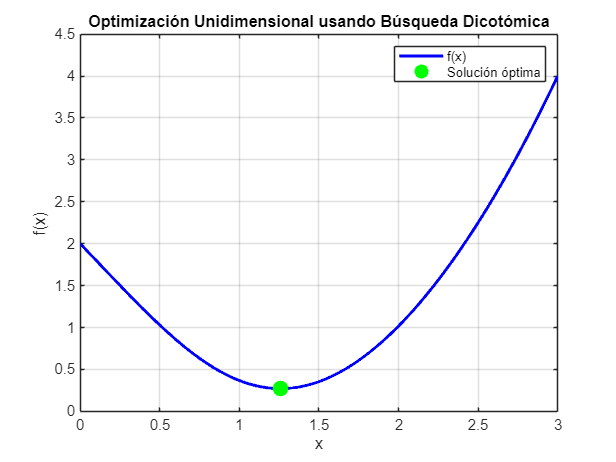

% Limpieza de la consola, variables y figuras
clc; clear; close all;

% Definir la función objetivo
f = @(x) (x-1).^2 + exp(-x.^2);  % Función unimodal

% Definir los límites del intervalo de búsqueda
a = 0;
b = 3;

% Parámetros de la búsqueda dicotómica
delta = 1e-6;  % Tolerancia (delta)

% Inicialización de las variables
max_iter = 100;  % Número máximo de iteraciones

% Obtener la solución óptima final
[f_opt, x_opt, iter] = secau(f, a, b, delta, max_iter);


% Graficar la función objetivo
x_vals = linspace(a, b, 1000);
y_vals = f(x_vals);

figure;
plot(x_vals, y_vals, 'b-', 'LineWidth', 2);
legend('f(x)');
hold on;
% Marcar la solución óptima en el gráfico
plot(x_opt, f_opt, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', 'Solución óptima');
xlabel('x');
ylabel('f(x)');
title('Optimización Unidimensional usando Búsqueda Dicotómica');
grid on;
hold off;

% Mostrar los resultados
disp('Punto óptimo (x):');

Punto óptimo (x):


disp(x_opt);

    1.2583



disp('Valor óptimo de f(x):');

Valor óptimo de f(x):


disp(f_opt);

    0.2720



## Anexo

function [f_opt, x_opt, iter] = secau(f, a, b, delta, max_iter)
    % Método de búsqueda con sección áurea
    % Entradas:
    %   f: función objetivo
    %   a, b: extremos iniciales del intervalo unimodal
    %   delta: tolerancia para la convergencia
    %   max_iter: número máximo de iteraciones
    %
    % Salidas:
    %   f_opt: valor de la función dónde se alcanza el óptimo  
    %   x_opt: punto donde se alcanza el óptimo
    %   iter: número de iteraciones realizadas


    % Paso 1: se define la proporción áurea
    alpha = (sqrt(5)-1)/2;

    % Paso 2: calcular intervalo
    xa = a + (1-alpha)*(b-a);
    xb = a + alpha*(b-a);

    % Paso 3: evaluación inicial de la función en los puntos xa y xb
    fa = f(xa);
    fb = f(xb);

    % Inicialización iteraciones
    iter = 0;

    % Paso 4: mientras (b - a) >= tol y no max_iter
    while (b - a) > delta && iter < max_iter
        iter = iter + 1;

        % Paso 5: actualizar el intervalo
        if fa >= fb
            a = xa;
            xa = xb;
            xb = a + alpha*(b-a);
            fa = fb;
            fb = f(xb);
        else
            b = xb;
            xb = xa;
            xa = a + (1-alpha)*(b-a);
            fb = fa;
            fa = f(xa);
        end

    end
    % Paso 6: Cálculo del mínimo
    x_opt = (a + b)/2;
    f_opt = f(x_opt);

end